clc;clear;

## 2.1.1


syms L R Kc Km Jm Bm B1 M1 l1 g J1

A= [[-R/L -Kc/L]; [Km/Jm -Bm/Jm]];
B= [1/L; 0];
C= [0 1];
D = 0;

syms s

I = eye(size(A));

G_sym = C*inv(s*I - A)*B + D;

G_sym

$$G\_sym = \frac{\mathrm{Km}}{\mathrm{Bm}\,R+\mathrm{Kc}\,\mathrm{Km}+\mathrm{Bm}\,L\,s+\mathrm{Jm}\,R\,s+\mathrm{Jm}\,L\,s^{2}}$$

## 2.1.2


L_val  = 0.00025;
R_val  = 0.5;
Kc_val = 0.48;
Km_val = 0.5;

Jm_val = 0.05;
Bm_val = 0.02;
B1_val = 0.125;

M1_val = 2;
l1_val = 0.3;

g_val  = 9.81;

%% 4. Substitute values
Result_sub = subs(G_sym,...
    [L R Kc Km Jm Bm B1 M1 l1 g],...
    [L_val R_val Kc_val Km_val Jm_val Bm_val B1_val M1_val l1_val g_val])

$$Result\_sub = \frac{1}{2\,\left(\frac{s^{2}}{80000}+\frac{5001\,s}{200000}+\frac{1}{4}\right)}$$

Result_sub = vpa(Result_sub,3)

$$Result\_sub = \frac{0.5}{1.25e-5\,s^{2}+0.025\,s+0.25}$$

## 2.1.3

[num, den] = numden(Result_sub);
poles = solve(den == 0, s)

$$poles = \left(\begin{array}{c} -1990.3515237596729070257795939331\\ -10.048476242160293232485736966579 \end{array}\right)$$

approx_poles = vpa(poles,3)

$$approx\_poles = \left(\begin{array}{c} -1990.0\\ -10.0 \end{array}\right)$$

## 2.1.4

F_a = subs(G_sym,...
    [L],...
    [0])

$$F\_a = \frac{\mathrm{Km}}{\mathrm{Bm}\,R+\mathrm{Kc}\,\mathrm{Km}+\mathrm{Jm}\,R\,s}$$

F_a = subs(F_a,...
    [Km Kc Bm R Jm],...
    [Km_val Kc_val Bm_val R_val Jm_val])

$$F\_a = \frac{1}{2\,\left(\frac{s}{40}+\frac{1}{4}\right)}$$

## 2.1.5


[num, den] = numden(F_a);
poles = solve(den == 0, s)

$$poles = -10$$

approx_poles = vpa(poles,3)

$$approx\_poles = -10.0$$

## 2.2.1

syms i theta omega u real
syms L R Kc Km Jm Bm B1 M1 l1 g real

J1 = M1*l1^2/3;

x = [i; theta; omega];

di = (-R*i - Kc*omega + u)/L;
dtheta = omega;
domega = (Km*i - (Bm+B1)*omega - M1*g*l1/2*sin(theta))/(Jm + J1);

f = [di;
     dtheta;
     domega]

$$f = \left(\begin{array}{c} -\frac{\mathrm{Kc}\,\omega -u+R\,i}{L}\\ \omega \\ -\frac{\omega \,\left(B_{1}+\mathrm{Bm}\right)-\mathrm{Km}\,i+\frac{M_{1}\,g\,l_{1}\,\sin\left(\theta \right)}{2}}{\frac{M_{1}\,{l_{1}}^{2}}{3}+\mathrm{Jm}} \end{array}\right)$$


y = theta

$$y = \theta$$


syms x1 x2 x3
f_sys = subs(f,...
    [i theta omega],...
    [x1 x2 x3])

$$f\_sys = \left(\begin{array}{c} -\frac{\mathrm{Kc}\,x_{3}-u+R\,x_{1}}{L}\\ x_{3}\\ -\frac{x_{3}\,\left(B_{1}+\mathrm{Bm}\right)-\mathrm{Km}\,x_{1}+\frac{M_{1}\,g\,l_{1}\,\sin\left(x_{2}\right)}{2}}{\frac{M_{1}\,{l_{1}}^{2}}{3}+\mathrm{Jm}} \end{array}\right)$$

y_sys = subs(y,...
    [i theta omega],...
    [x1 x2 x3])

$$y\_sys = x_{2}$$

## 2.2.2


% Calculate equilibrium values for the system
theta_e = pi/4;
omega_e = 0;

eq1 = subs(di,[theta omega],[theta_e omega_e]) == 0;
eq2 = subs(domega,[theta omega],[theta_e omega_e]) == 0;

sol = solve([eq1 eq2],[i u]);

i_e = simplify(sol.i);
u_e = simplify(sol.u);
Cm_e = Km*i_e;

x_e = [i_e u_e omega_e]

$$x\_e = \left(\begin{array}{ccc} \frac{\sqrt{2}\,M_{1}\,g\,l_{1}}{4\,\mathrm{Km}} & \frac{\sqrt{2}\,M_{1}\,R\,g\,l_{1}}{4\,\mathrm{Km}} & 0 \end{array}\right)$$

## 2.2.3


%Matrices
A = jacobian(f,x);
B = jacobian(f,u);

C = jacobian(y,x);
D = jacobian(y,u);

A_eq = subs(A,[i theta omega],[i_e theta_e omega_e])

$$A\_eq = \left(\begin{array}{ccc} -\frac{R}{L} & 0 & -\frac{\mathrm{Kc}}{L}\\ 0 & 0 & 1\\ \frac{\mathrm{Km}}{\frac{M_{1}\,{l_{1}}^{2}}{3}+\mathrm{Jm}} & -\frac{\sqrt{2}\,M_{1}\,g\,l_{1}}{4\,\left(\frac{M_{1}\,{l_{1}}^{2}}{3}+\mathrm{Jm}\right)} & -\frac{B_{1}+\mathrm{Bm}}{\frac{M_{1}\,{l_{1}}^{2}}{3}+\mathrm{Jm}} \end{array}\right)$$

B_eq = subs(B,[i theta omega],[i_e theta_e omega_e])

$$B\_eq = \left(\begin{array}{c} \frac{1}{L}\\ 0\\ 0 \end{array}\right)$$


C_eq = subs(C,[i theta omega],[i_e theta_e omega_e])

$$C\_eq = \left(\begin{array}{ccc} 0 & 1 & 0 \end{array}\right)$$

D_eq = subs(D,[i theta omega],[i_e theta_e omega_e])

$$D\_eq = 0$$


params = [L R Kc Km Jm Bm B1 M1 l1 g];
values = [0.00025 0.5 0.48 0.5 0.05 0.02 0.125 2 0.3 9.81];

A_num = double(subs(A_eq,params,values))

A_num = 1.0e+03 *

   -2.0000         0   -1.9200
         0         0    0.0010
    0.0045   -0.0189   -0.0013


B_num = double(subs(B_eq,params,values))

B_num =         4000
           0
           0


C_num = double(subs(C_eq,params,values))

C_num =      0     1     0


D_num = double(subs(D_eq,params,values))

D_num = 0

## 2.2.4

I = eye(size(A_eq));

G_sym = simplify(C_eq * inv(s*I - A_eq) * B_eq + D_eq);
G_sym = collect(G_sym, s)

$$G\_sym = \frac{12\,\mathrm{Km}}{\left(4\,L\,M_{1}\,{l_{1}}^{2}+12\,\mathrm{Jm}\,L\right)\,s^{3}+\left(4\,M_{1}\,R\,{l_{1}}^{2}+12\,B_{1}\,L+12\,\mathrm{Bm}\,L+12\,\mathrm{Jm}\,R\right)\,s^{2}+\left(12\,B_{1}\,R+12\,\mathrm{Bm}\,R+12\,\mathrm{Kc}\,\mathrm{Km}+3\,\sqrt{2}\,L\,M_{1}\,g\,l_{1}\right)\,s+3\,\sqrt{2}\,M_{1}\,R\,g\,l_{1}}$$

G_num = subs(G_sym,params,values)

$$G\_num = \frac{6}{\frac{33\,s^{3}}{100000}+\frac{132087\,s^{2}}{200000}+\left(\frac{8829\,\sqrt{2}}{2000000}+\frac{15}{4}\right)\,s+\frac{8829\,\sqrt{2}}{1000}}$$

## 2.2.5

[num, den] = numden(G_num);
poles = solve(den == 0, s);
approx_poles = vpa(poles,4)

$$approx\_poles = \left(\begin{array}{c} -2.847+3.294\,\mathrm{i}\\ -2.847-3.294\,\mathrm{i}\\ -1996.0 \end{array}\right)$$

## 2.2.6

values_sim = [0 0.5 0.48 0.5 0.05 0.02 0.125 2 0.3 9.81];
G_sym_sim = subs(G_sym,params,values_sim)

$$G\_sym\_sim = \frac{6}{\frac{33\,s^{2}}{50}+\frac{15\,s}{4}+\frac{8829\,\sqrt{2}}{1000}}$$

## 2.2.7

[num_sim, den_sim] = numden(G_sym_sim);
poles = solve(den_sim == 0, s);
approx_poles = vpa(poles,4)

$$approx\_poles = \left(\begin{array}{c} -2.841-3.294\,\mathrm{i}\\ -2.841+3.294\,\mathrm{i} \end{array}\right)$$

## 3.1.2

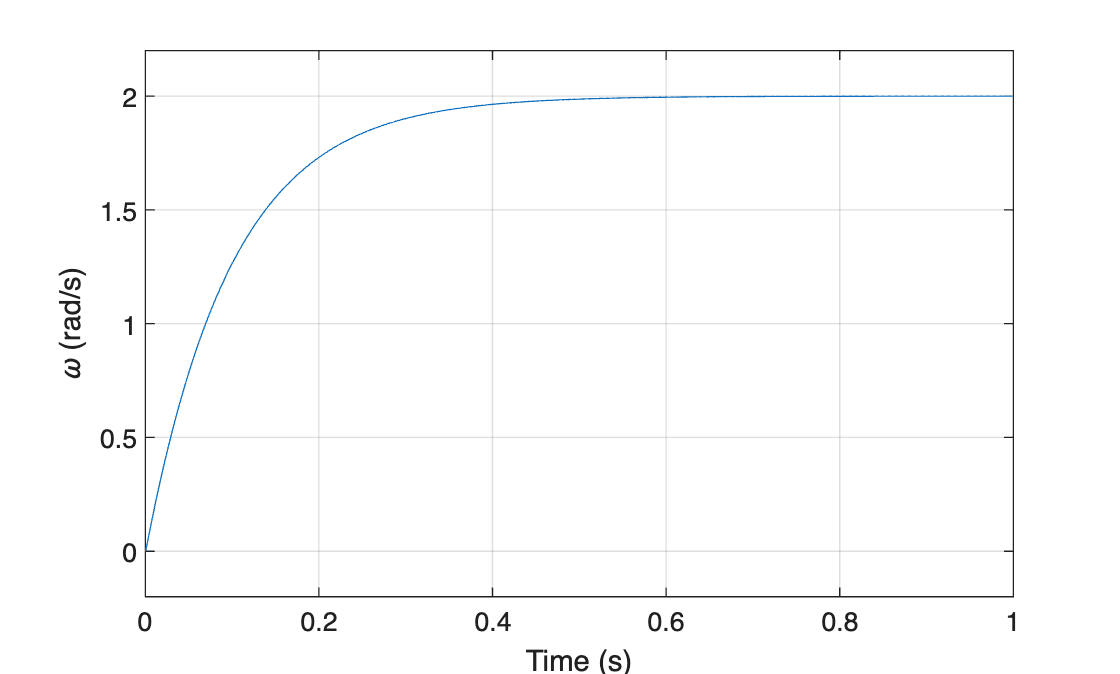

timeOfSimulation = 1;
dt = 0.001;

t = (0:dt:timeOfSimulation)';
u = ones(size(t));

simin = [t u];

set_param('TP3_3_1_2', ...
    'SolverType','Fixed-step', ...
    'Solver','ode4', ...
    'FixedStep',num2str(dt), ...
    'StopTime',num2str(timeOfSimulation));

out = sim('TP3_3_1_2');

omega_sim = out.omega.data;
time = out.omega.time;

scale = 10;   % percentage padding

ymin = min(omega_sim);
ymax = max(omega_sim);

range = ymax - ymin;

limits = [ ...
    ymin - scale/100 * range, ...
    ymax + scale/100 * range ...
];

plot(time, omega_sim)
xlabel('Time (s)')
ylabel('\omega (rad/s)')
ylim(limits)
grid on

## 3.1.3

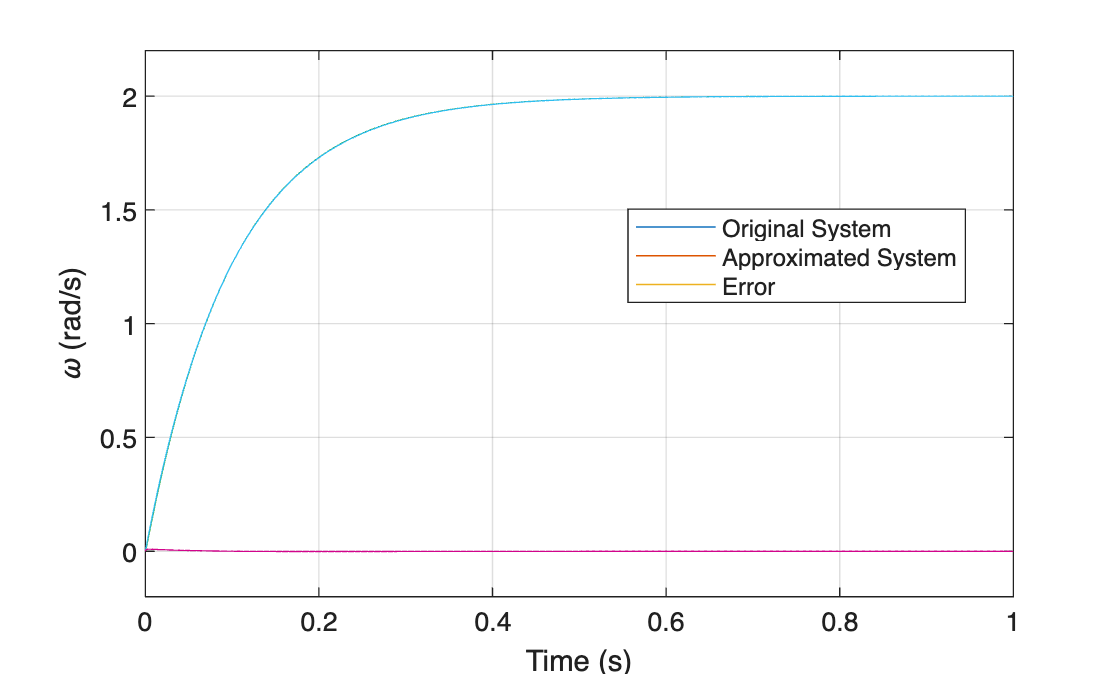

timeOfSimulation = 1;
dt = 0.001;

t = (0:dt:timeOfSimulation)';
u = ones(size(t));

simin = [t u];

L_val=0;

set_param('TP3_3_1_3', ...
    'SolverType','Fixed-step', ...
    'Solver','ode4', ...
    'FixedStep',num2str(dt), ...
    'StopTime',num2str(timeOfSimulation));

out = sim('TP3_3_1_3');

omega_sim_a = out.omega.data;
time = out.omega.time;

scale = 10;   % percentage padding

ymin = min(omega_sim_a);
ymax = max(omega_sim_a);

range = ymax - ymin;

limits = [ ...
    ymin - scale/100 * range, ...
    ymax + scale/100 * range ...
];

plot(time, omega_sim) 
hold on
plot(time, omega_sim_a)
plot(time, omega_sim_a-omega_sim)
xlabel('Time (s)')
ylabel('\omega (rad/s)')
ylim(limits)
legends = {'Original System' 'Approximated System' 'Error'};
legend(legends, 'Location', 'best')
grid on

## 3.2.1

## 3.2.2

## 3.2.3

## 3.3.1

## 3.3.2

## 3.3.3

## 3.4.1

## 3.4.2

## 3.4.3